clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);

## Same real uncertainty for every input with alpha = 0


$$\Delta=\delta \textbf{I}, \delta\in[-1,1]$$


param = control.DesignProcedureSOF(param,0,{[-1,1]},0);

Evaluation of design procedure for real uncertainties 
Eigenvalues of the decoupled systems are all negative 


ans =   -3.7230 + 0.0000i  -0.1570 + 0.5455i  -0.1570 - 0.5455i  -3.7410 + 0.0000i  -0.1672 + 0.5510i  -0.1672 - 0.5510i  -3.6909 + 0.0000i  -0.1730 + 0.5548i  -0.1730 - 0.5548i  -3.6894 + 0.0000i  -0.1738 + 0.5593i  -0.1738 - 0.5593i


Eigenvalues of the coupled systems are all negative 


ans =   -3.4587 + 0.0000i  -3.3013 + 0.0000i  -3.2463 + 0.0000i  -3.1610 + 0.0000i  -0.2945 + 0.7349i  -0.2945 - 0.7349i  -0.3686 + 0.8275i  -0.3686 - 0.8275i  -0.4083 + 0.8539i  -0.4083 - 0.8539i  -0.4380 + 0.8739i  -0.4380 - 0.8739i


-0.233478, 0.000000, 0.000000, 0.000000, 
-0.233478, 0.000000, 0.000000, 0.000000, 
-0.233478, 0.000000, 0.000000, 0.000000, 
-0.233478, 0.000000, 0.000000, 0.000000, 
-0.233478, 0.000000, 0.000000, 0.000000, 
-0.233478, 0.000000, 0.000000, 0.000000, 
-0.233478, 0.000000, -0.000000, 0.000000, 
-0.233478, 0.000000, 0.000000, 0.000000, 
-0.233478, -0.000000, -0.000000, -0.000000, 
-0.246030, 0.000000, 0.000000, 0.000000, 
-0.235492, 0.000000, 0.000000, 0.000000, 
-0.233478, 0.000000, 0.000000, 0.000000, 
-0.602067, 0.000000, 0.000000, 0.000000, 


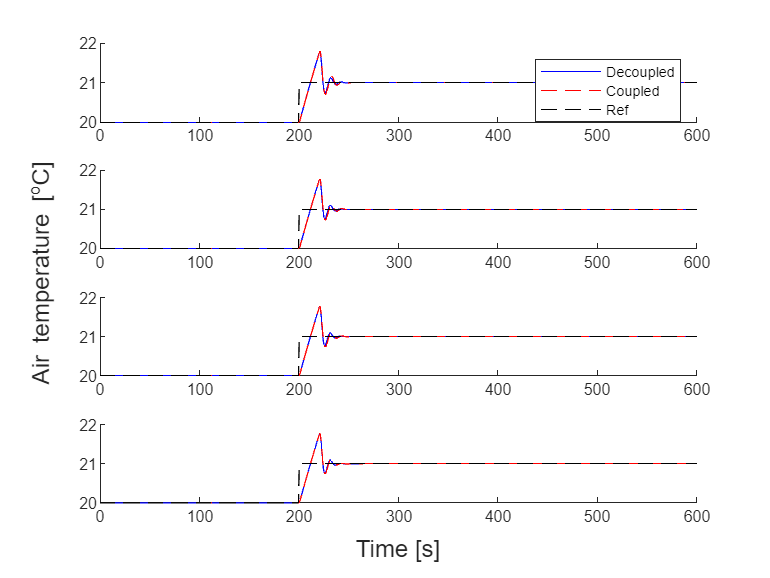

util.SimulateStep(param,"Examination_Output_Feedback_alpha0",0);

## Same real uncertainty for every input with alpha = 0.5


$$\Delta=\delta \textbf{I}, \delta\in[-1,1]$$


param = control.DesignProcedureSOF(param,0,{[-1,1]},0.5);

Evaluation of design procedure for real uncertainties 
Eigenvalues of the decoupled systems are all negative 


ans =   -0.6237 + 1.5698i  -0.6237 - 1.5698i  -1.2895 + 0.0000i  -0.6805 + 1.6503i  -0.6805 - 1.6503i  -1.2145 + 0.0000i  -0.7099 + 1.7193i  -0.7099 - 1.7193i  -1.1172 + 0.0000i  -0.6941 + 1.6781i  -0.6941 - 1.6781i  -1.1487 + 0.0000i


Eigenvalues of the coupled systems are all negative 


ans =   -0.9574 + 2.9363i  -0.9574 - 2.9363i  -0.9895 + 3.4703i  -0.9895 - 3.4703i  -1.0111 + 3.6750i  -1.0111 - 3.6750i  -1.0066 + 3.7992i  -1.0066 - 3.7992i  -0.6305 + 0.0000i  -0.5585 + 0.0000i  -0.5437 + 0.0000i  -0.5243 + 0.0000i


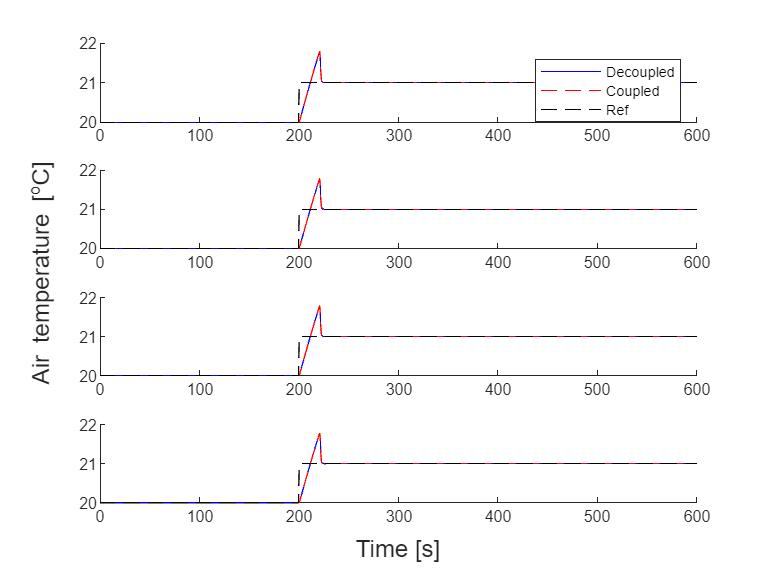

util.SimulateStep(param,"Examination_Output_Feedback_alpha",0);